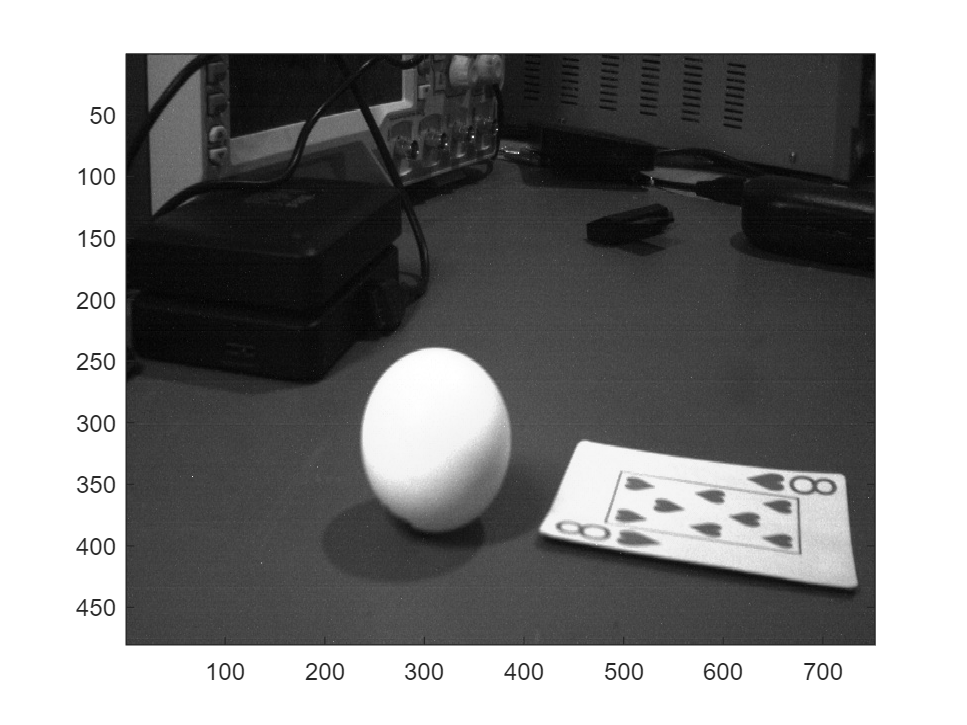

Frame_1 = imread(uigetfile('.png''.jpg'));
formated_frame_1 = rgb2gray(Frame_1);
colormap gray
imagesc(formated_frame_1)


cols = 752

cols = 752

rows = 480

rows = 480


w = 100

w = 100

h = 100

h = 100


binary = zeros(rows,cols);
for x = 1:cols
    for y = 1:rows
        if (formated_frame_1(y,x) > 150)
            binary(y,x) = 1;
        end
    end
end
imshow(formated_frame_1)
[center, radius] = imfindcircles(formated_frame_1,[25 75])

center =   308.9743  309.8738


radius = 71.3872

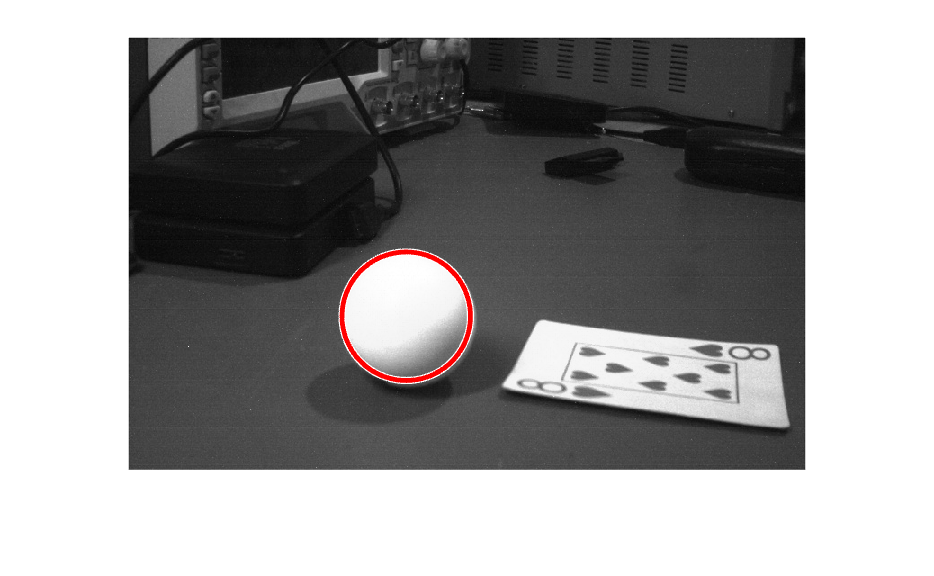

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


%plot(viscircles(center, radius, 'Color', 'red'))
%hold on
viscircles(center, radius, 'Color', 'red')

scatter(center(1), center(2))



Frame_2 = imread(uigetfile('.png''.jpg'));
formated_frame_2 = rgb2gray(Frame_2);
formated_frame_2 = im2bw(formated_frame_2)

formated_frame_2 = 480×752 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

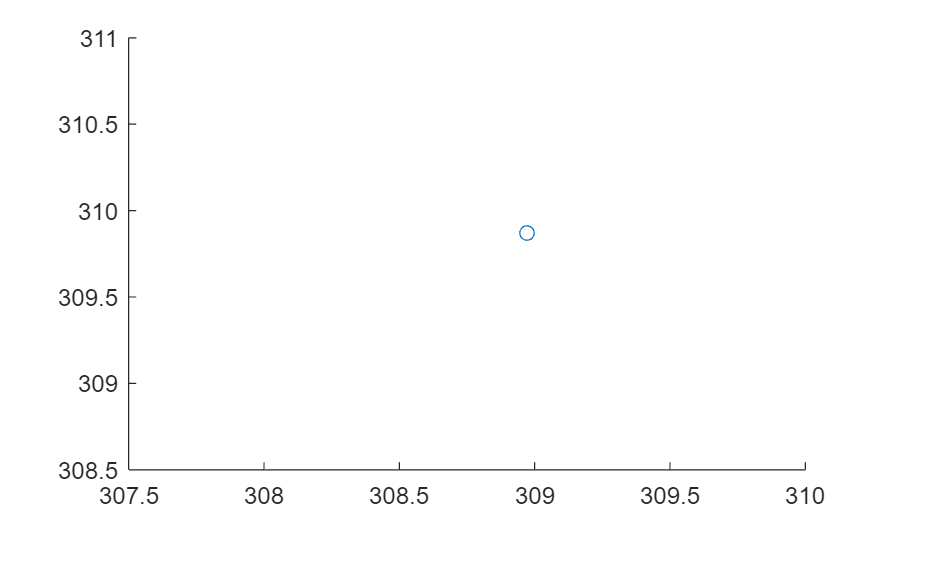

colormap gray

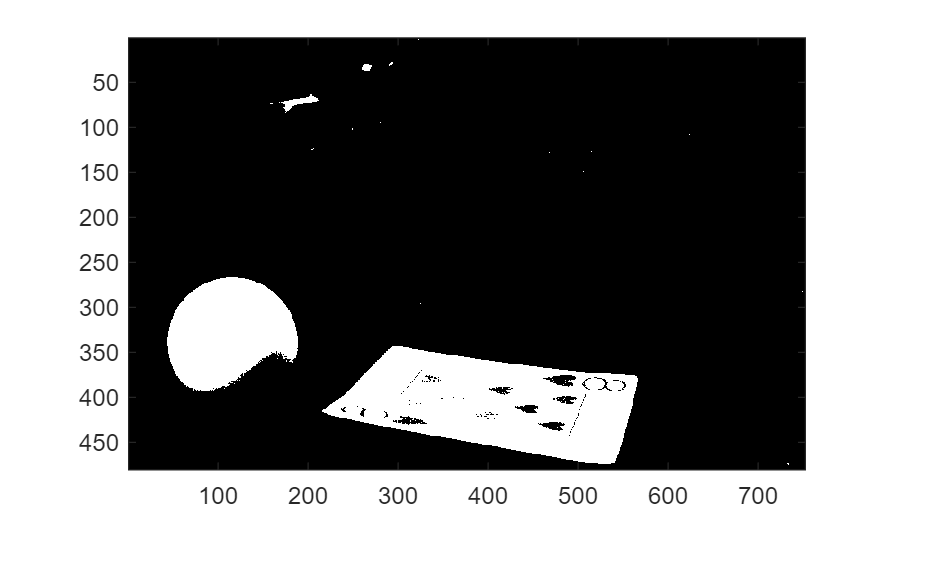

imagesc(formated_frame_2)


binary2 = zeros(rows,cols);
for x = 1:cols
    for y = 1:rows
        if (formated_frame_2(y,x) > 150)
            binary2(y,x) = 1;
        end
    end
end
imshow(formated_frame_2)
[center, radius] = imfindcircles(formated_frame_2,[25 75], "Sensitivity", 0.85)

center =   115.7677  337.8432


radius = 72.1378

%plot(viscircles(center, radius, 'Color', 'red'))
hold on
viscircles(center, radius, 'Color', 'm')

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


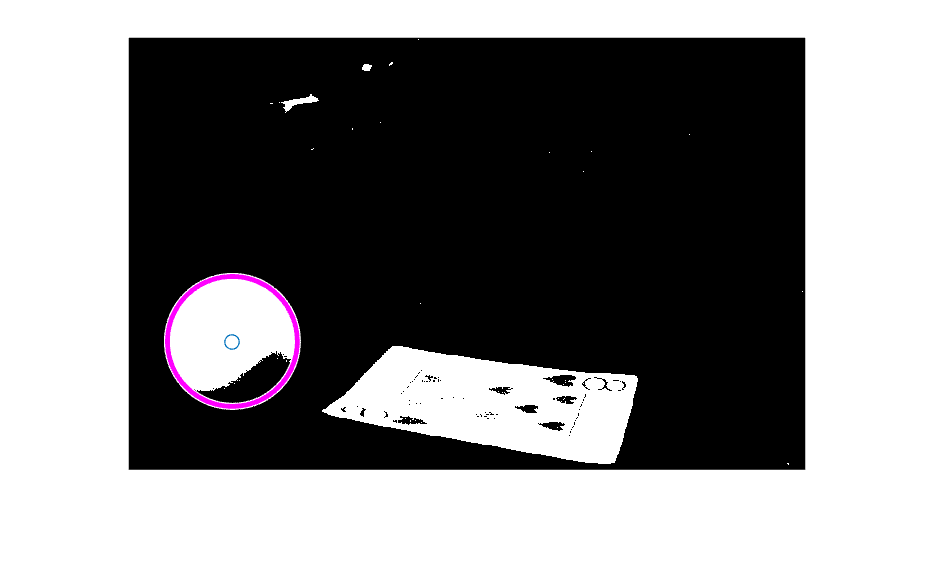

scatter(center(1), center(2))